# **Video Processing: Laboratory 1:**

Adrià Garcia Coscolla: u232256

Ernest Fosch Muntané: u196572

### **Task 1.a:**

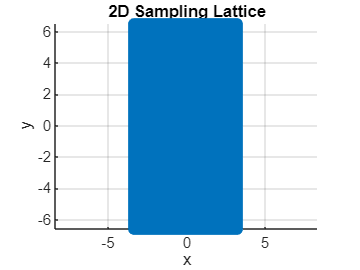

a=6;
b=2;
N=264; %We will have NxN samples

[m,n]= meshgrid(-N/2:N/2-1, -N/2:N/2-1);

psi= @(x,y)cos(2*pi*a*x) .* cos(2*pi*b*y) + ...
0.7*sin(pi*a*b*(x+y)) + ...
0.5*cos(pi*(a + 0.5*a*b)*x - pi*b*y); 

V=[1/40,0;0,1/20];

x = V(1,1)*m + V(1,2)*n;
y = V(2,1)*m + V(2,2)*n;

psi_s = psi(x, y); %sampling of the function: psi_s = psi(Vn)

%2D plot of the sample lattice grid.
figure;
scatter(x(:), y(:), 50, 'filled');  % 50 = marker size
axis equal;
xlabel('x'); ylabel('y');
title('2D Sampling Lattice');
grid on;

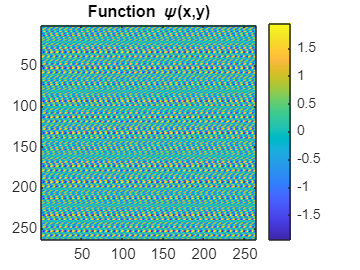


%2D plot of the sampled signal (psi)
imagesc(psi_s);
colorbar;
axis equal tight;  % optional, keeps aspect ratio correct
title('Function \psi(x,y)');

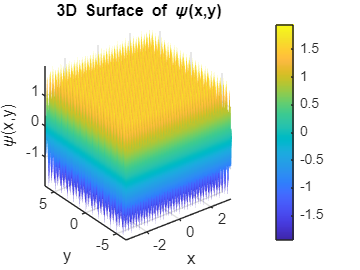


%3D plot of the sampled signal (psi)
figure;
surf(x, y, psi_s);        % create 3D surface
shading interp;            % smooth shading
colorbar;                  % show color scale
axis tight;                % fit axes tightly
xlabel('x'); ylabel('y'); zlabel('\psi(x,y)');
title('3D Surface of \psi(x,y)');

### **Task 1.b:**

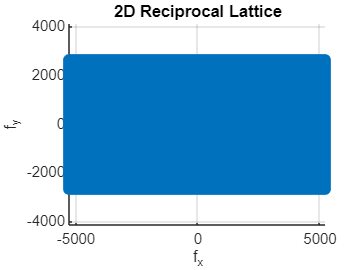

%reciprocal latice
U = inv(V');
[m,n]= meshgrid(-N/2:N/2-1, -N/2:N/2-1);
f_x = U(1,1)*m + U(1,2)*n;
f_y = U(2,1)*m + U(2,2)*n;

%2D plot of the reciprocal lattice grid.
figure;
scatter(f_x(:), f_y(:), 50, 'filled');  % 50 = marker size
axis equal;
xlabel('f_x'); ylabel('f_y');
title('2D Reciprocal Lattice');
grid on;

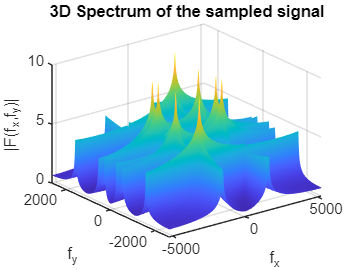



% 2D FFT
F = fft2(psi_s);

% Shift zero-frequency to the center
F_shifted = fftshift(F);

% Magnitude spectrum
F_mag = abs(F_shifted);
% Optional: logarithmic scale for better visualization
F_log = log(1 + F_mag);

figure;
surf(f_x, f_y, F_log);
shading interp;
xlabel('f_x'); ylabel('f_y'); zlabel('|F(f_x,f_y)|');
title('3D Spectrum of the sampled signal');